# **Detecció de presència de jugadors del Barça en la escena.**

### **1.**Seleccioneu una (o més) imatges on apareguin jugadors del Barça, que serviran de model.

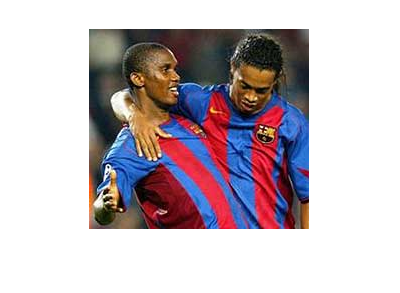

clc;
clear;
close all;

Im = imread("barcelona\28.jpg");
imshow(Im);

### Seleccioneu manualment un (o més) fragments de la imatge que continguin una part significativa de la samarreta.

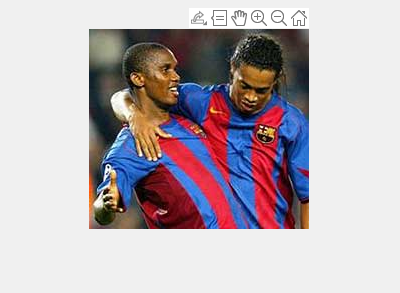

rect = getrect;

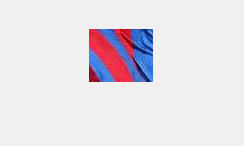

Im2 = imcrop(Im,rect);
imshow(Im2);

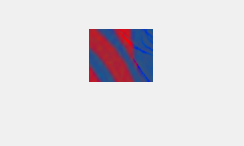

Im2 = normalitzar(Im2);
imshow(Im2);

### 2.Calculeu l’histograma de color dels fragments dels models. Aquests seran els histogrames model que usareu per buscar la samarreta en noves imatges.

hM = getHistHSV(Im2);
%bar(hM);

### 3.Construïu histogrames de color de fragments de totes les imatges de tots els equips. Aquests fragments no poden ser seleccionats de forma manual, s'han de seleccionar de forma exhaustiva mitjançant finestra lliscant o de forma aleatòria

%Obtenim puntuacions de tots els equips
myFolder = 'barcelona';
barcelona_score=teamscore(myFolder,hM);
myFolder = 'madrid';
madrid_score=1-teamscore(myFolder,hM);
myFolder = 'acmilan';
acmilan_score=1-teamscore(myFolder,hM);
myFolder = 'chelsea';
chelsea_score=1-teamscore(myFolder,hM);
myFolder = 'juventus';
juventus_score=1-teamscore(myFolder,hM);
myFolder = 'liverpool';
liverpool_score=1-teamscore(myFolder,hM);
myFolder = 'psv';
psv_score=1-teamscore(myFolder,hM);

total_score=acmilan_score+barcelona_score+chelsea_score+juventus_score+liverpool_score;
total_score=total_score+madrid_score+psv_score;
total_score=total_score/7;

disp('acmilan score:');

acmilan score:


disp(acmilan_score);

    0.7778



disp('barcelona score:');

barcelona score:


disp(barcelona_score);

    0.7778



disp('chelsea score:');

chelsea score:


disp(chelsea_score);

    0.6944



disp('juventus score:');

juventus score:


disp(juventus_score);

    0.8056



disp('liverpool score:');

liverpool score:


disp(liverpool_score);

    0.8889



disp('madrid score:');

madrid score:


disp(madrid_score);

    0.9167



disp('psv score:');

psv score:


disp(psv_score);

    0.5556



disp('falsos negatius:');

falsos negatius:


disp(1-barcelona_score);

    0.2222



falsospositius=total_score*7-barcelona_score;
falsospositius=(6-falsospositius)/6;
disp('falsos positius:');

falsos positius:


disp(falsospositius);

    0.2269



disp('total score:');

total score:


disp(total_score);

    0.7738



### 4. Compareu aquests histogrames obtinguts, amb els histogrames model

imageArray = imread("juventus\01.jpg");
model = imageArray;
%obtenir fragments dividint imatge (FER LOOP)
grid = 5; 
[row, col, channels] = size(model);
for i=0:grid-1
    for j=0:grid-1
        cell = imcrop(model, [j*col/grid i*row/grid col/grid row/grid]); 
        cell = normalitzar(cell);
        %cell(isnan(cell))=0;
        hC = getHistHSV(cell);
        euclideanDistance(hM,hC)
        chiSquare(hM,hC)
    end
end

ans = 0.7670

ans = 0.6433

ans = 0.6537

ans = 0.5044

ans = 0.5166

ans = 0.3975

ans = 0.6778

ans = 0.5114

ans = 0.7012

ans = 0.5407

ans = 0.8342

ans = 0.7365

ans = 0.6042

ans = 0.4614

ans = 0.6766

ans = 0.5109

ans = 0.5273

ans = 0.3909

ans = 0.5454

ans = 0.3887

ans = 0.8565

ans = 0.7638

ans = 0.6856

ans = 0.5249

ans = 0.5483

ans = 0.4223

ans = 0.6331

ans = 0.5137

ans = 0.5827

ans = 0.4319

ans = 0.8614

ans = 0.7905

ans = 0.7522

ans = 0.6384

ans = 0.8002

ans = 0.6897

ans = 0.9374

ans = 0.8908

ans = 0.7395

ans = 0.6220

ans = 0.8376

ans = 0.7436

ans = 0.7773

ans = 0.6678

ans = 0.9352

ans = 0.9134

ans = 0.8515

ans = 0.7790

ans = 0.8919

ans = 0.8350

### 5. A partir dels resultats de les comparacions determinar en quines imatges apareix la samarreta del Barça

### 6. Per a fer l'histograma, useu primer l'espai RGB i després repetiu l'experiment usant l'espai HSV. Compareu els resultats

#### *Auxiliar functions*

function [distChi, score] = compareHist(hM, hC)
    distChi = chiSquare(hM,hC);
    total = distChi; %total = distChi + distEuc
    score = distChi/2; % score = distChi/total + distEu/total
end

function res = chiSquare(h1,h2)
    qi = sum(h1,'all');
    vi = sum(h2,'all');
    Q = h1./qi;
    V = h2./vi;
    N = (Q-V).^2;
    D = (Q+V);
    dist = N./D;
    res = sum(dist,'all','omitnan')/2;
end

function res = euclideanDistance(h1,h2)
    qi = sum(h1,'all');
    vi = sum(h2,'all');
    Q = h1./qi;
    V = h2./vi;
    N = (Q-V).^2;
    dist = (N.^0.5);
    res = sum(dist,'all','omitnan')/2;
end


function[Norm] = normalitzar(Im)
 R = double(Im(:,:,1));
 G = double(Im(:,:,2));
 B = double(Im(:,:,3));
 I = (R+G+B);
 r = R./I;
 g = G./I;
 b = B./I;
 Norm = imgaussfilt(cat(3,r,g,b));
 Norm(isnan(Norm)) = 0;
 
end

function score= teamscore(myFolder,hM)
    filePattern = fullfile(myFolder, '*.jpg');
    jpegFiles = dir(filePattern);
    encerts=0;
    for k = 1:length(jpegFiles)
        baseFileName = jpegFiles(k).name;
        fullFileName = fullfile(myFolder, baseFileName);
        imageArray = imread(fullFileName);
        model = imageArray;
        %model = normalitzar(model);
        hComp = {};
        bestscore=1;
        grid = 5;
        [row, col, channels] = size(model);
        for i=0:grid-1
            for j=0:grid-1
                cell = imcrop(model, [j*col/grid i*row/grid col/grid row/grid]); 
                cell = normalitzar(cell);           
                hC = getHistHSV(cell); 
                res=chiSquare(hM,hC);
                if(bestscore>res) 
                    bestscore=res;
                end
        
                %% SELECCIONAR BEST FRAGMENTS I GUARDARLOS A hComp{}
                %%compareHist(h,hModel);
            end
        end
        if(bestscore<0.30) 
            encerts=encerts+1;    
        end
    end
    score=encerts/36;
end

function h = getHistHSV(Im)
    Im = rgb2hsv(Im);
    hH = imhist(Im(:,:,1),32);
    hS = imhist(Im(:,:,1),32); 
    %hV = imhist(Im(:,:,1),32); %% value not necessary
    h = cat(2,hH,hS);
end